clear;

A = [0 1; 2 -1];
B = [1 2; -1 4];
C = [1 2; -4 1];

%========================
eA = eig(A);
%========================
%{
syms s;
I = eye(size(A, 1));
W = C*inv(s*I-A)*B;
Wsimp = simplify(W);
vpa(Wsimp, 4);
det(W);
[num, den] = numden(W);
num = sym(num);
den = sym(den);
solution = solve(num,s);
vpa(solution, 4);
solution = solve(den,s);
vpa(solution, 4);
%}
%=======================
U = [B A*B];
ru = rank(U);
V = [C; C*A];
rv = rank(V);
D = [0 0; 0 0];
U_out = [C*U D];
ruout = rank(U_out);

%=======================
t = 0:0.01:5

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


%{
y_i1 = exp(t)-2*exp(-2*t);
y_i2 = 8*exp(t)+2*exp(-2*t);
y_i3 = -exp(t)-4*exp(-2*t);
y_i4 = 8*exp(t)-4*exp(-2*t);


figure('Position', [100 100 800 400])

plot(t, y_i1,'b-', 'LineWidth',1.5);
hold on
plot(t, y_i2,'g-', 'LineWidth',1.5);
plot(t, y_i3,'c-.', 'LineWidth',1.5);
plot(t, y_i4,'r-.', 'LineWidth',1.5);

grid()
title('Graph $y_{i.r.}$','Interpreter','latex',  'FontSize', 14)
legend('$y_{i.r.11}(t)$', '$y_{i.r.12}(t)$', '$y_{i.r.21}(t)$', '$y_{i.r.22}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off
%}

%======================

%{
y_s1 = exp(t)+ exp(-2*t)-2;
y_s2 = 8*exp(t)-exp(-2*t)-7;
y_s3 = -exp(t)+2*exp(-2*t)-1;
y_s4 = 8*exp(t)+2*exp(-2*t)-10;


figure('Position', [100 100 800 400])

plot(t, y_s1,'b-', 'LineWidth',1.5);
hold on
plot(t, y_s2,'g-', 'LineWidth',1.5);
plot(t, y_s3,'c-.', 'LineWidth',1.5);
plot(t, y_s4,'r-.', 'LineWidth',1.5);

grid()
title('Graph $y_{s.r.}$','Interpreter','latex',  'FontSize', 14)
legend('$y_{s.r.11}(t)$', '$y_{s.r.12}(t)$', '$y_{s.r.21}(t)$', '$y_{s.r.22}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off
%}

%========================
syms w real;

ww1 = (-5*w^2-8-6*1j*w-1j*w^3)/((w^2+2)^2-w^2);
ww2 = (-10j*w^3-4*w^2-28-34*1j*w)/((w^2+2)^2-w^2);
ww3 = (-7*w^2+5j*w^3-4+8j*w)/((w^2+2)^2-w^2);
ww4 = (4j*w^3+16*w^2-40+28j*w)/((w^2+2)^2-w^2);

P = [real(ww1) real(ww2); real(ww3) real(ww4)];
Q = [imag(ww1) imag(ww2); imag(ww3) imag(ww4)];

Afc = simplify(sqrt(P.*P + Q.*Q))

$$Afc = \begin{array}{l} \left(\begin{array}{cc} \frac{\sqrt{{\left|w^{3}+6\,w\right|}^{2}+{\left(5\,w^{2}+8\right)}^{2}}}{\sigma_{1}} & \frac{2\,\sqrt{25\,w^{6}+174\,w^{4}+345\,w^{2}+196}}{\sigma_{1}}\\ \frac{\sqrt{{\left|5\,w^{3}+8\,w\right|}^{2}+{\left(7\,w^{2}+4\right)}^{2}}}{\sigma_{1}} & \frac{4\,\sqrt{w^{6}+30\,w^{4}-31\,w^{2}+100}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=w^{4}+3\,w^{2}+4 \end{array}$$

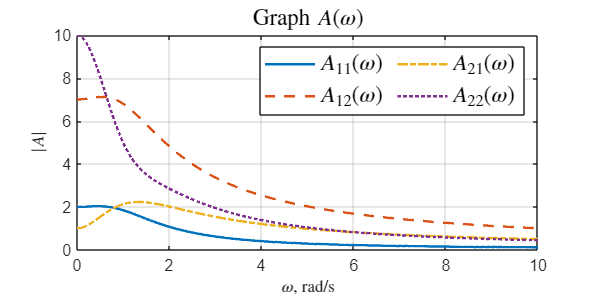


w_x = 0:0.01:10;

Afc1 = double(subs(Afc(1,1), w, w_x));
Afc2 = double(subs(Afc(1,2), w, w_x));
Afc3 = double(subs(Afc(2,1), w, w_x));
Afc4 = double(subs(Afc(2,2), w, w_x));

figure('Position', [100 100 800 400]);
plot(w_x, Afc1, '-', 'LineWidth',1.5);
hold on
plot(w_x, Afc2, '--', 'LineWidth',1.5);
plot(w_x, Afc3, '-.', 'LineWidth',1.5);
plot(w_x, Afc4, ':', 'LineWidth',1.5);

grid()
title('Graph $A(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$A_{11}(\omega)$', '$A_{12}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$|A|$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off


w_l = logspace(-1, 3, 1000);

LAfc1 = 20 * log10(Afc(1,1))

$$LAfc1 = \frac{20\,\log\left(\frac{\sqrt{{\left|w^{3}+6\,w\right|}^{2}+{\left(5\,w^{2}+8\right)}^{2}}}{w^{4}+3\,w^{2}+4}\right)}{\log\left(10\right)}$$

LAfc2 = 20 * log10(Afc(1,2))

$$LAfc2 = \frac{20\,\log\left(\frac{2\,\sqrt{25\,w^{6}+174\,w^{4}+345\,w^{2}+196}}{w^{4}+3\,w^{2}+4}\right)}{\log\left(10\right)}$$

LAfc3 = 20 * log10(Afc(2,1))

$$LAfc3 = \frac{20\,\log\left(\frac{\sqrt{{\left|5\,w^{3}+8\,w\right|}^{2}+{\left(7\,w^{2}+4\right)}^{2}}}{w^{4}+3\,w^{2}+4}\right)}{\log\left(10\right)}$$

LAfc4 = 20 * log10(Afc(2,2))

$$LAfc4 = \frac{20\,\log\left(\frac{4\,\sqrt{w^{6}+30\,w^{4}-31\,w^{2}+100}}{w^{4}+3\,w^{2}+4}\right)}{\log\left(10\right)}$$

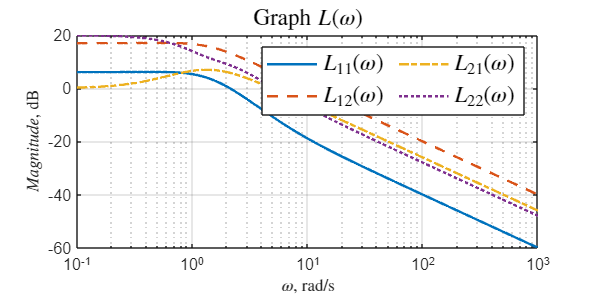


LAfc1 =  double(subs(LAfc1, w, w_l));
LAfc2 =  double(subs(LAfc2, w, w_l));
LAfc3 =  double(subs(LAfc3, w, w_l));
LAfc4 =  double(subs(LAfc4, w, w_l));

figure('Position', [100 100 800 400]);
semilogx(w_l, LAfc1, '-', 'LineWidth',1.5);
hold on
semilogx(w_l, LAfc2, '--', 'LineWidth',1.5);
semilogx(w_l, LAfc3, '-.', 'LineWidth',1.5);
semilogx(w_l, LAfc4, ':', 'LineWidth',1.5);

grid()
title('Graph $L(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$L_{11}(\omega)$', '$L_{12}(\omega)$', '$L_{21}(\omega)$', '$L_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$Magnitude$, dB', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off

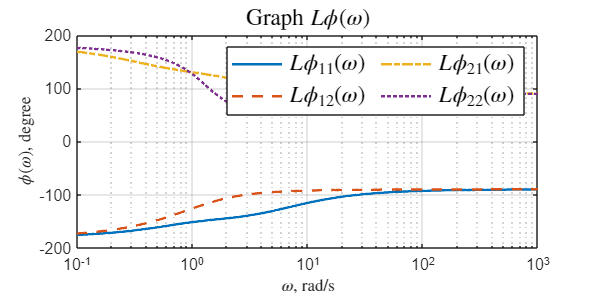



phi_1 = atan2(Q(1,1),P(1,1));
phi_2 = atan2(Q(1,2),P(1,2));
phi_3 = atan2(Q(2,1),P(2,1));
phi_4 = atan2(Q(2,2),P(2,2));

Phi = [phi_1 phi_2; phi_3 phi_4];

phi_1 = double(subs(Phi(1,1), w, w_l));
phi_2 = double(subs(Phi(1,2), w, w_l));
phi_3 = double(subs(Phi(2,1), w, w_l));
phi_4 = double(subs(Phi(2,2), w, w_l));

figure('Position', [100 100 800 400]);
semilogx(w_l, phi_1*180/pi, '-', 'LineWidth',1.5);
hold on
semilogx(w_l, phi_2*180/pi, '--', 'LineWidth',1.5);
semilogx(w_l, phi_3*180/pi, '-.', 'LineWidth',1.5);
semilogx(w_l, phi_4*180/pi, ':', 'LineWidth',1.5);

grid()
title('Graph $L\phi (\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$L\phi_{11}(\omega)$', '$L\phi_{12}(\omega)$', '$L\phi_{21}(\omega)$', '$L\phi_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$\phi (\omega)$, degree', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off

%}
%=========================================================
%=========================================================

D = [4 0; 0 -1];
Bf = [1 2; -1 1];
Df = [-1 0; 0 -1];
Cz = [2 0; -1 1];
Dz = [1 0; 0 4];


U = [B A*B];
V = [Cz; Cz*A];

U_oy = [C*U D];
rank(U_oy);

U_oz = [C*U Dz];
rank(U_oz);

rank(U);
rank(V);

syms s

W = C * (s * eye(2) - A)^-1 * B + D;
simplify(W);
det(W);

W = Cz * (s * eye(2) - A)^-1 * B + Dz;
simplify(W);
det(W);

Gw = [0 -6 0 0 0 0;
    6 0 0 0 0 0;
    0 0 0 -2 0 0;
    0 0 2 0 0 0;
    0 0 0 0 0 -3;
    0 0 0 0 3 0];

Yg = [0 0 0 0 2.5 2.5;
    0 0 0 0 2.5 2.5];
Y1 = [0 0 0 3 0 0;
    4 0 0 0 0 0];
Y2 = [3 0 0 0 0 0;
    0 0 0 5 0 0];

wg0 = [1; 0; 1; 0; 1; 1];

x0 = [1;1];
xw0 = [wg0; x0];

%Yg = [3/2 3/2 0 0 0 0; -1/2 1/2 0 0 0 0];
%Y1 = [0 0 0 3 0 0;  0 0 0 0 0 11];
%Y2 = [0 0 0 0 0 1;  0 0 0 8 0 0];


%K = [];
%Kw = [];
arr_0 = [0 0; 0 0; 0 0; 0 0; 0 0; 0 0];
Ab = [Gw arr_0; Bf*Y1 A]

Ab =      0    -6     0     0     0     0     0     0
     6     0     0     0     0     0     0     0
     0     0     0    -2     0     0     0     0
     0     0     2     0     0     0     0     0
     0     0     0     0     0    -3     0     0
     0     0     0     0     3     0     0     0
     8     0     0     3     0     0     0     1
     4     0     0    -3     0     0     2    -1


Bb = [0 0; 0 0; 0 0; 0 0; 0 0; 0 0; B]

Bb =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     1     2
    -1     4


Cb = [Df*Y2-Yg C]

Cb =    -3.0000         0         0         0   -2.5000   -2.5000    1.0000    2.0000
         0         0         0   -5.0000   -2.5000   -2.5000   -4.0000    1.0000



%L = []

syms t
simplify(Yg*expm(Gw * t) * wg0);
syms t
simplify(Y1*expm(Gw * t) * wg0);
syms t
simplify(Y2*expm(Gw * t) * wg0);

eig(A)

ans =      1
    -2


Y = [0 1; 1 1];
G = [-2.5 1; 0 -2.5];
Vyg = [Y; Y*G];
rank(Vyg);


cvx_begin sdp

variable P(2, 2)

A*P-P*G == B*Y;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



d =det(P);
P;
K = -Y*pinv(P);
eig(A+B*K);

la = 2j;
Check_m = [A+B*K-la*eye(2) B; Cz+Dz*K Dz];
rank(Check_m);



cvx_begin sdp

variable Pp(2, 6)
variable Kw(2, 6)

Pp*Gw - (A+B*K)*Pp-Bf*Y1==B*Kw;
(Cz + Dz*K)*Pp+Dz*Kw == Yg
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Kw;

Kb = [Kw K];

V = [Cb;
    Cb*Ab;
    Cb*Ab^2;
    Cb*Ab^3;
    Cb*Ab^4;
    Cb*Ab^5;
    Cb*Ab^6;
    Cb*Ab^7];
rank(V);

eig(Ab);

Gb = [-1 0 0 0 0 0 0 0;
    0 -1.5 0 0 0 0 0 0;
    0 0 -2.5 0 0 0 0 0;
    0 0 0 -3 0 0 0 0;
    0 0 0 0 -3.5 0 0 0;
    0 0 0 0 0 -4 0 0;
    0 0 0 0 0 0 -4.5 0;
    0 0 0 0 0 0 0 -5];
Yb = [1 0;1 1;1 1;1 1;1 1;1 1;1 1;1 1];

U = [Yb Ab*Yb Ab^2*Yb Ab^3*Yb Ab^4*Yb Ab^5*Yb Ab^6*Yb Ab^7*Yb];
rank(U);

cvx_begin sdp

variable Q(8, 8)

Gb*Q -Q*Ab == Yb*Cb;
cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 



Q;
det(Q);

L = pinv(Q)*Yb;

eig(Ab+L*Cb);
%========================================
%{
open_system('task_2_sim');
set_param('task_2_sim/x', 'VariableName', 'x')
set_param('task_2_sim/y', 'VariableName', 'y')
set_param('task_2_sim/u', 'VariableName', 'u')
set_param('task_2_sim/ex', 'VariableName', 'ex')
set_param('task_2_sim/ew', 'VariableName', 'ew')
set_param('task_2_sim/x_', 'VariableName', 'x_')
set_param('task_2_sim/w', 'VariableName', 'w')
set_param('task_2_sim/w_', 'VariableName', 'w_')
set_param('task_2_sim/g', 'VariableName', 'g')
set_param('task_2_sim/f1', 'VariableName', 'f1')
set_param('task_2_sim/f2', 'VariableName', 'f2')
set_param('task_2_sim/yf', 'VariableName', 'yf')

set_param('task_2_sim/z', 'VariableName', 'z')



out = sim('task_2_sim');
figure('Position', [100 100 800 400])

plot(out.ew,'-', 'LineWidth',1.5);
%hold on
%plot(out.g.Time, out.g.Data(:,2),'-.', 'LineWidth',1.5);
%plot(out.wf_,':', 'LineWidth',1.5);
%{
plot(out.w.Time, out.w.Data(:,4),'-', 'LineWidth',1.5);
hold on
plot(out.w.Time, out.w.Data(:,5),'-', 'LineWidth',1.5);
plot(out.w.Time, out.w.Data(:,6),'-', 'LineWidth',1.5);
plot(out.w_.Time, out.w_.Data(:,4),'-.', 'LineWidth',1.5);
plot(out.w_.Time, out.w_.Data(:,5),'-.', 'LineWidth',1.5);
plot(out.w_.Time, out.w_.Data(:,6),'-.', 'LineWidth',1.5);
%}
grid()
title('Graph $e_w(t) = w(t) - \hat{w}(t)$ ','Interpreter','latex',  'FontSize', 14)
legend('$e_{w1}(t)$', '$e_{w2}(t)$', ...
    '$e_{w3}(t)$', '$e_{w4}(t)$', '$e_{w5}(t)$', '$e_{w6}(t)$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
%legend('$y_{1}(t)$', '$y_{}(t)$', '$w_{6}(t)$', '$\hat{w}_{4}(t)$', '$\hat{w}_{5}(t)$', '$\hat{w}_{6}(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
%legend('$w_{f1}(t)$', '$w_{f2}(t)$', '$w_{f3}(t)$', '$w_{f4}(t)$', ...
%    '$\hat{w}_{f1}(t)$', '$\hat{w}_{f2}(t)$', '$\hat{w}_{f3}(t)$','$\hat{w}_{f4}(t)$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
%ylim([-35 30])
hold off
%}